# `Setup`

clearvars; close all; % clear all workspace variables and close all figures

`% INPUT PARAMETERS`

rob.size = 12;  % distance from robot center to edge midpoint in IJ coordinates
rob.diag = 14;  % distance from robot center to corner in IJ coordinates

min_triEdge = 2; % target minimum edge length for triangulation mesh

cornerLoc = 1;  % desired starting location of path planning algorithm. Valid values for this parameter are:
% 1 (farthest valid starting corner from polyshape centroid)
% 2 (closest valid starting corner from polyshape centroid)
% 3 (polyshape centroid)

editedPGM_path = "/Users/tylerlonga/Desktop/code/maps/zach_map_edited_rotated.pgm";  % file path of post-edited lidar map in PGM format

numRobots = 1; % number of robots to be utilized in decomposed work area

`% ADDITIONAL PARAMETERS`

mergeTri = true; % unchecked skip triangle merging, checked perform triangle merging (default)
if mergeTri; minTri.base = .5; minTri.height = .5; end % minumum values for base and height when determining triangles to merge

rosSetup = false; % unchecked skip connecting to ROS network (default), checked connect to ROS network

% due to potential differences between the raw occupancy map origin and
% the default occupancy map origin in MATLAB (0,0), this difference can be
% corrected by importing the raw occupancy map
importRawMap = false;   % unchecked skip importing raw occupancy map (default), checked import raw occupancy map

wholeRoom = false;   % unchecked perform map decomposition (default), checked do not perform map decomposition

enableRetasking = true;    % unchecked do not reallocate tasks, checked reallocate tasks (default)

resolution = 50;   % occupancy map resolution in cells per meter

mergeRob.size = rob.size+3; % padded robot size to consider when identifying polygons to merge
mergeRob.diag = rob.diag+3; % padded robot diagonal length to consider when identifying polygons to merge

`% CONNECT TO ROS NETWORK`

if rosSetup
    rosshutdown()   % make sure any ROS sessions are closed
    rosinit("http://X.X.X.X:11311") % initialize ROS network and connect to host
end

`% IMPORT RAW MAP`

if importRawMap
    try
        % try to subscribe to /map topic and receive the sent message
        sub = rossubscriber("/map",DataFormat='struct');
        msg = receive(sub);

        % generate an occupancy map with the received map message
        rawMap = rosReadOccupancyGrid(msg);
        show(rawMap)    % visually inspect the imported raw occupancy map
    catch
        % if unable to subscribe to /map topic, load raw map from local save
        savedMap = load('ros_occMap.mat');
        rawMap = savedMap.occupancyMapObj;
        show(rawMap); clear savedMap;
    end
else
    rawMap = [];
end

# `Image Processing `

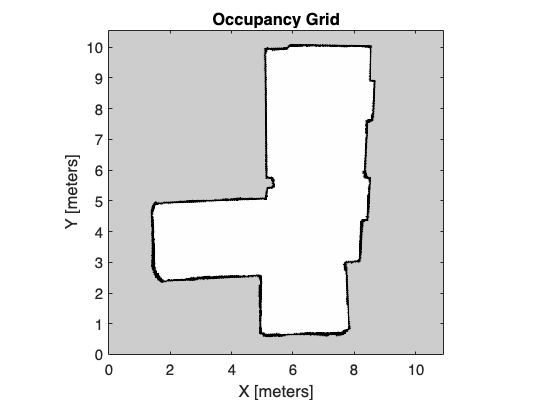

tic
editedPGM = imread(editedPGM_path); % load in pgm image of post edited lidar scan

% normalize the image to values between 0 and 1 then convert to occupancy
% values by subtracting from 1
editedMap_occ = 1 - double(editedPGM)/255;

% generate an occupancy map from the occupancy values
editedMap = occupancyMap(editedMap_occ,resolution);
show(editedMap) % visually inspect the generated occupancy map

`% IDENTIFY EXTERIOR BOUNDARY AND INTERIOR OBSTACLE BOUNDARIES`

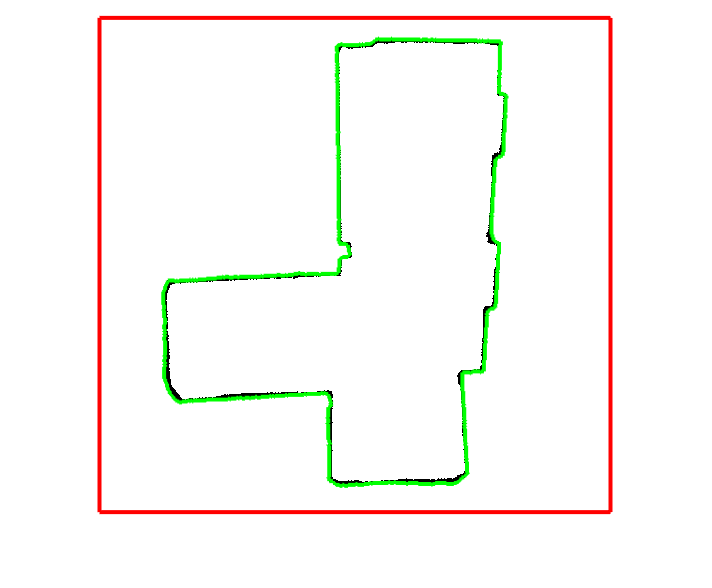

[exteriorIJ, interiorIJ] = identifyBoundaries(editedPGM);


% determine if the exterior boundary has been misidentified as an interior obstacle,
% if so set the interior obstacle as the exterior boundary
obsNum = fieldnames(interiorIJ);    % determine number of identified interior obstacles
if (length(exteriorIJ) < 10) && (numel(obsNum) == 1)
    % reduce the number of points describing the exterior boundary
    exteriorIJ = reducepoly(interiorIJ.obs1,.01);
    removeObs = 0;  % do not remove interior obstacles
else
    removeObs = 1;  % do remove interior obstacles
end

% convert the exterior boundary points from IJ to XY coordinates
exteriorXY = grid2world(editedMap,exteriorIJ);

`% POLYSHAPE REPRESENTATION`

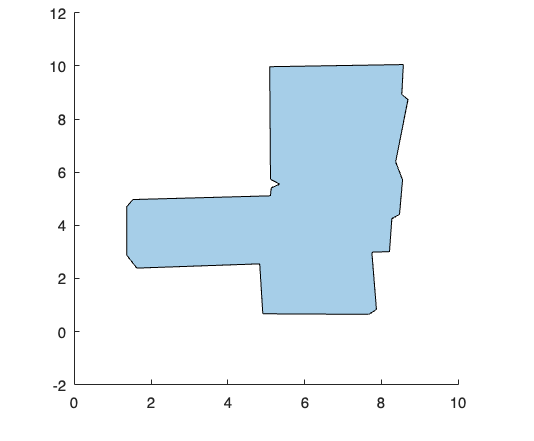

% generate a polyshape of the room from the exterior boundary points
room = polyshape(exteriorXY(:,1),exteriorXY(:,2));
plot(room)


% if applicable, remove the identified interior obstacles from the room polyshape
if removeObs == 1
    for i = 1:numel(obsNum)
        % convert the identifed interior obstacles points from IJ to XY coordinates
        interiorXY = grid2world(editedMap,interiorIJ.(obsNum{i}));

        % reduce the number of points describing the obstacle
        reducedObs = reducepoly(interiorXY,.01);

        % generate a polyshape representing the obstacle
        obs = polyshape(reducedObs(:,1),reducedObs(:,2));

        % remove the obstacle polyshape from the room polyshape
        room = subtract(room,obs);
    end
    plot(room); % visually inspect the resulting polyshape
end

# `Map Decomposition`

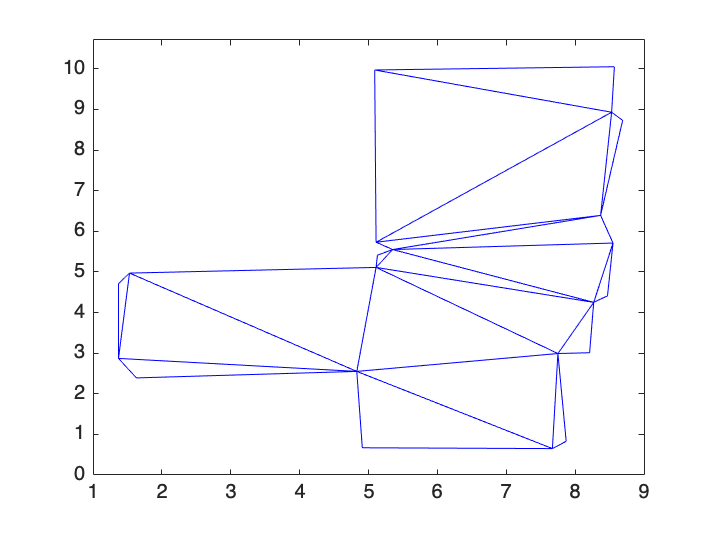

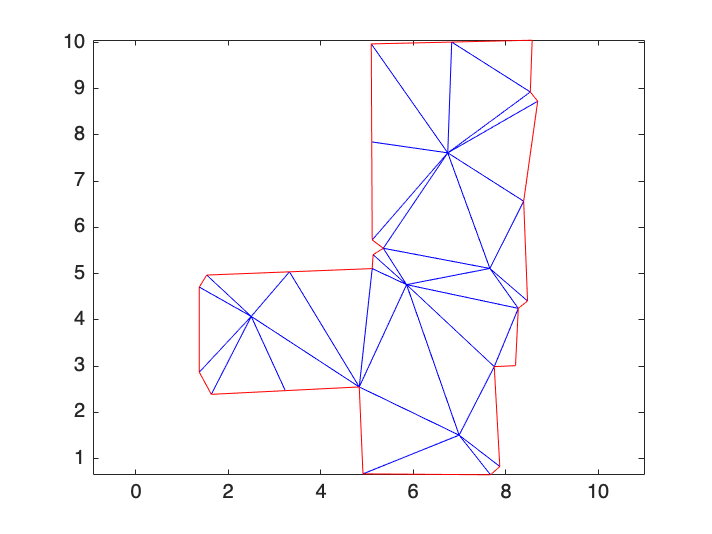

# of subtours: 2
# of subtours: 2
# of subtours: 5
# of subtours: 2
# of subtours: 1


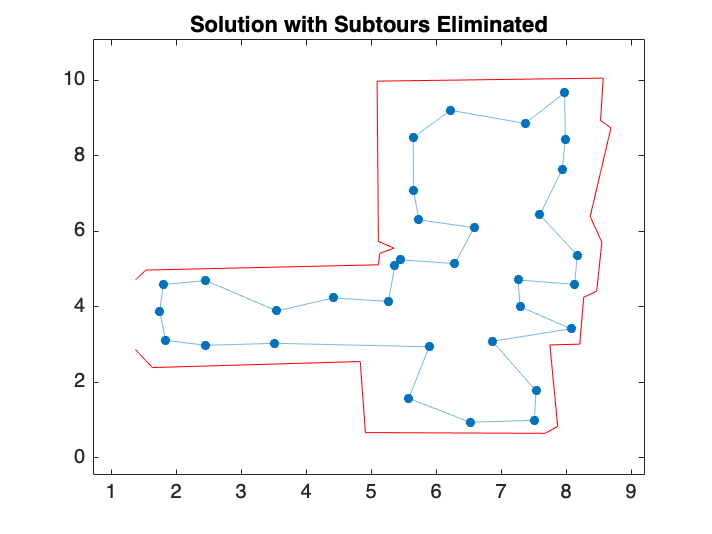

     0



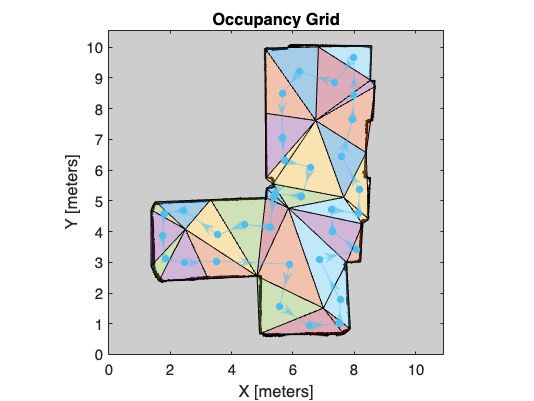

if wholeRoom
    programTime = toc;

    % get occupancy map and starting location of room
    [localMap, startXY] = poly2occgrid(room, 0, rawMap, rob, cornerLoc, resolution);

    % convert starting location to IJ coordinates
    startIJ = world2grid(localMap,startXY);

    % call path planning algorithm to perform complete coverage
    figure; deadlock_cntr = 0;
    [localMap,time,turnCount,overlap,pathLength,deadlock_cntr] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr);

    % determine the number of cleaned and uncleaned cells
    localOcc = occupancyMatrix(localMap);
    clean = length(find((localOcc>.4)&(localOcc<.6)));
    unclean = length(find(localOcc<.1));

    % display simualtion data
    fprintf("Simulation runtime: %.2fs",time)
    fprintf("Turn count: %d",turnCount)
    fprintf("Overlap: %d",overlap)
    fprintf("Path length: %.2f",pathLength)

    covEff = clean / (unclean+clean);
    fprintf("Coverage efficiency: %.2f%%",covEff*100)

    fprintf("Number of deadlock events: %d",deadlock_cntr)
    fprintf("Strategy planning algorithm runtime: %.2fs",programTime)
else
    % decompose polyshape using triangular mesh
    tri = triDecomposition(room, min_triEdge);

    % determine an initial optimal path passing through all triangle centroids using
    % Traveling Salesman Problem (TSP) algorithm
    [Gdir, tri.nodeList] = directedTSP(tri, room.Vertices);

    % overlay triangular mesh and identified optimal path on the edited map
    show(editedMap); hold on;
    plot(tri.shape)
    hGraph = plot(Gdir,'XData',tri.centroid(:,1),'YData',tri.centroid(:,2),'LineStyle','none','NodeLabel',{});
    highlight(hGraph,Gdir,'LineStyle','-')
    hold off

    if mergeTri
        % determine if a triangle needs to be merged
        tri2merge = identifyTri2merge(tri, minTri)

#### `% MERGE IDENTIFIED TRIANGLES`

tri2merge =      1
     8
    16
    19
    21
    24
    25
    31
    33


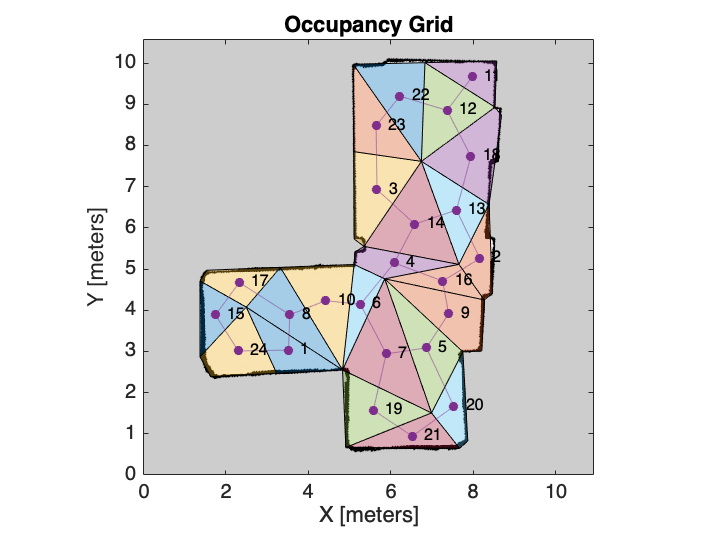

# of subtours: 4
# of subtours: 2
# of subtours: 2
# of subtours: 1


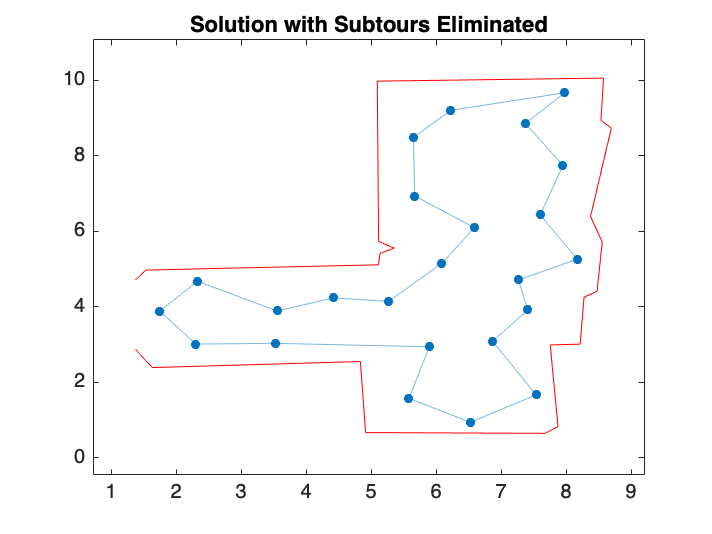

     0



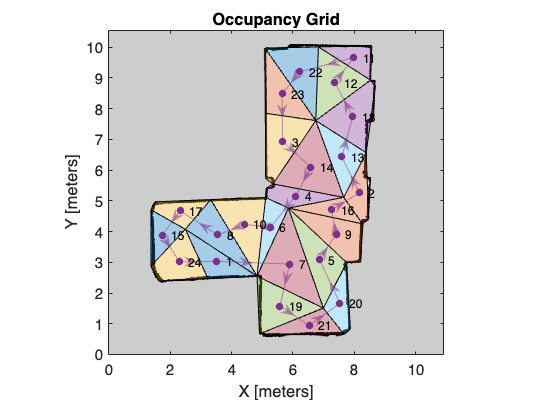

        % configure waitbar to monitor merging process
        triWait = waitbar(0,'Initializing Merging Process','Name','Merging Triangles...',...
            'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

        % configure a cancel button on waitbar
        setappdata(triWait,'canceling',0);

        offset = 0; % counter to track the number of nodes removed from the original node list
        for i = 1:length(tri2merge)
            % check if cancel button has been pressed
            if getappdata(triWait,'canceling'); break; end

            % identify node to be merged by subtracting the offset from the current node value
            node2merge = tri2merge(i,1)-offset;

            % update waitbar and message
            waitbar(i/length(tri2merge),triWait,sprintf('Merging triangle %d of %d',i,length(tri2merge)))

            % fprintf('%d\n',node2merge+offset) % display current node being merged

            % get current polygon connectivity
            Gtri = polyConn(tri.shape);

            % determine which neighboring node to merge with
            neighbor2merge = polyNeighbor(Gtri, node2merge, tri.shape);

            % merge neighbor node with current triangle node
            neighborTri = tri.shape(neighbor2merge);
            currentTri = tri.shape(node2merge);
            tri.shape(neighbor2merge) = union(neighborTri,currentTri);    % save resulting merged polygon to neighbor node index in shape list

            offset = offset+1;  % increment offset value
            tri.shape(node2merge) = [];   % remove merged triangle node from shape list
        end

        delete(triWait) % delete waitbar

        % get current polygon connectivity post merge
        Gtri = polyConn(tri.shape);

        % update centroid values of new polyshapes
        [x,y] = centroid(tri.shape);
        tri.centroid = [x;y]';

        % visually inspect polygon connectivity
        show(editedMap); hold on;
        plot(tri.shape)
        plot(Gtri,'XData',tri.centroid(:,1),'YData',tri.centroid(:,2))
        hold off;

        % determine a final optimal path passing through all triangles using TSP algorithm
        [Gdir, tri.nodeList] = directedTSP(tri, room.Vertices);

        % visually inspect resulting TSP path
        show(editedMap); hold on;
        plot(tri.shape)
        hGraph = plot(Gdir,'XData',tri.centroid(:,1),'YData',tri.centroid(:,2),'LineStyle','none');
        highlight(hGraph,Gdir,'LineStyle','-')
        hold off
    end

#### `% GENERATE BOUNDING BOXES`

    tri.nodeList(end,:) = []; % remove repeated node at end of node list

    % convert merged triangle polygons into bounding boxes
    for i = 1:length(tri.nodeList)

        % obtain bounding box XY limits
        [xlim,ylim] = boundingbox(tri.shape(tri.nodeList(i,1)));

        % identify min and max of XY limits
        xmin = min(xlim); xmax = max(xlim);
        ymin = min(ylim); ymax = max(ylim);

        % generate a polyshape of the bounding box and add to shape list
        polyMin = [xmin,ymin;xmax,ymin;xmax,ymax;xmin,ymax];
        polybox.shape(i) = polyshape(polyMin);
    end
    
    % determine centroid values of bounding boxes
    [x,y] = centroid(polybox.shape);
    polybox.centroid = [x;y]';

    % create a polyshape representing the area outside the room
    [xlim,ylim] = boundingbox(room);
    xmin = min(xlim); xmax = max(xlim);
    ymin = min(ylim); ymax = max(ylim);
    polyMin = polyshape([xmin,ymin;xmax,ymin;xmax,ymax;xmin,ymax]);
    roomOutside = subtract(polyMin,room);
    % plot(roomOutside)

#### `% CLEAN UP BOUNDING BOXES`

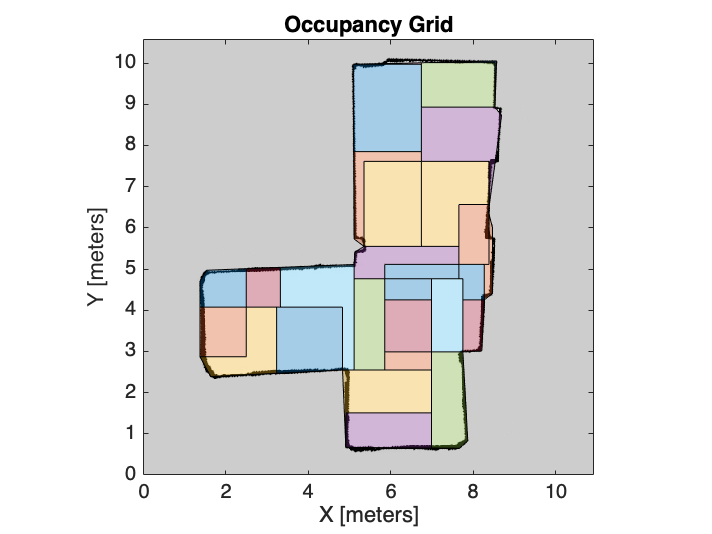

    % configure waitbar to monitor clean up process
    cleanWait = waitbar(0,'Initializing Clean Up Process','Name','Cleaning Up Bounding Boxes...',...
        'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

    % configure a cancel button on waitbar
    setappdata(cleanWait,'canceling',0);

    % clean up bounding boxes by removing overlaps and areas outside the room
    figure; show(editedMap); hold on;
    offset = 0;     % counter to track the number of bounding boxes removed from the original shape list
    for i = 1:length(polybox.shape)-offset
        % check if cancel button has been pressed
        if getappdata(cleanWait,'canceling'); break; end

        % identify bounding box to be cleaned up by subtracting the offset from the current index value
        polyIdx = i - offset;

        % update waitbar and message
        waitbar(i/length(polybox.shape)-offset,cleanWait,sprintf('Cleaning up bounding box %d of %d',i,length(polybox.shape)-offset))

        % fprintf('%d\n',polyIdx+offset)  % display current bounding box index being cleaned

        currentpoly = polybox.shape(polyIdx); % identify the current bounding box

        % determine the region of intersection (ROI) between the current bounding box
        % and the area outside the room then remove it from the current bounding box
        roomintsec = intersect(currentpoly,roomOutside);
        currentpoly = subtract(currentpoly,roomintsec);

        Gbox = polyConn(polybox.shape); % get current polygon connectivity

        % determine current bounding box neighbors
        [row,col] = find(Gbox.Edges.EndNodes==polyIdx);
        index = [row col]; neighbors = [];

        for j = 1:height(index)
            if index(j,2) == 1
                neighbors(j,1) = Gbox.Edges.EndNodes(index(j,1),2);
            elseif index(j,2) == 2
                neighbors(j,1) = Gbox.Edges.EndNodes(index(j,1),1);
            end
        end

        % remove current bounding box neighbor overlaps
        for k = 1:height(neighbors)
            % determine the ROI between current bounding box and neighbor
            polyintsec = intersect(currentpoly,polybox.shape(neighbors(k)));

            % check if the ROI is valid
            if height(polyintsec.Vertices) == 0
                continue;
            else
                % remove the ROI from the current bounding box if its area is
                % greater than the neighbor, else remove the ROI from the neighbor
                if area(currentpoly) > area(polybox.shape(neighbors(k)))
                    currentpoly = subtract(currentpoly,polyintsec);
                else
                    polybox.shape(neighbors(k)) = subtract(polybox.shape(neighbors(k)),polyintsec);
                end
            end
        end

        % check if the current bounding box is valid following removal of neighbor overlaps
        if height(currentpoly.Vertices) == 0
            polybox.shape(polyIdx) = [];   % remove current bounding box from list
            offset = offset+1;          % increment offset counter by 1
            continue;
        else
            polybox.shape(polyIdx) = currentpoly;  % save the cleaned up bounding box to the original shape list index
            plot(currentpoly)
        end
    end
    hold off;

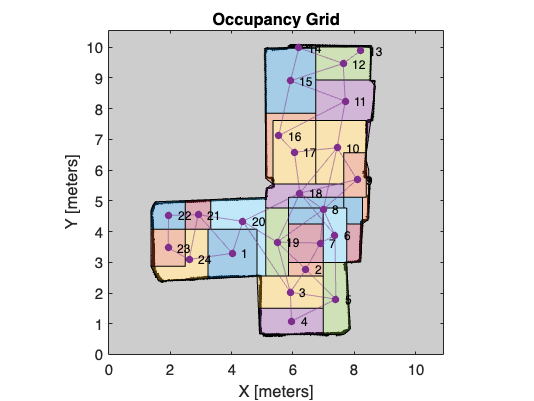


    delete(cleanWait) % delete waitbar

    % update centroid values of bounding boxes
    [x,y] = centroid(polybox.shape);
    polybox.centroid = [x;y]';

    % get current bounding box connectivity post clean up
    Gbox = polyConn(polybox.shape);

    % visually inspect bounding box connectivity
    figure; show(editedMap); hold on;
    plot(polybox.shape)
    plot(Gbox,'XData',polybox.centroid(:,1),'YData',polybox.centroid(:,2))
    hold off;

#### `% PREPARE AND IDENTIFY BOUNDING BOXES TO MERGE`

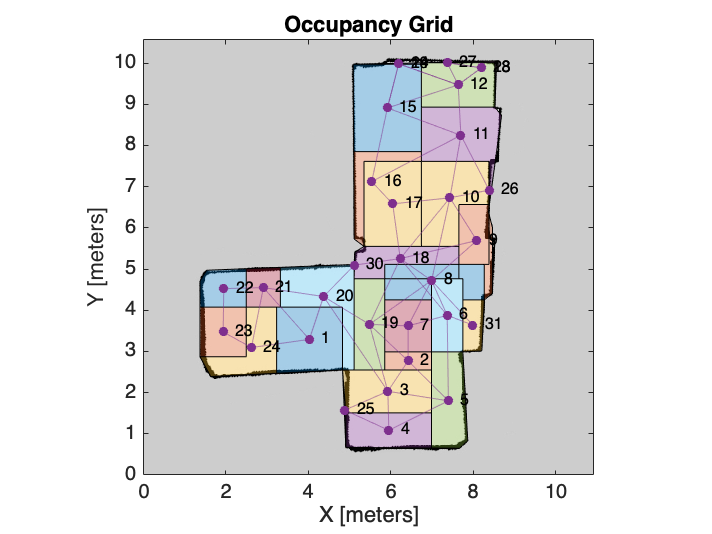

    % identify any slivers formed during the clean up process
    for i = 1:length(polybox.shape)
        currentpoly = polybox.shape(i); % identify current bounding box
        polynosliver = rmslivers(currentpoly,.05);  % remove any slivers from current bounding box
        polysliver = subtract(currentpoly,polynosliver);    % save the polyshape consisting of the removed slivers

        % check if the removed slivers polyshape is valid, if so append to end
        % of shape list
        if height(polysliver.Vertices) == 0
            continue;
        else
            polybox.shape(1,end+1) = polysliver;
        end

        % check if the polygon with slivers removed is valid, if so save
        % to the original polygon index
        if height(polynosliver.Vertices) == 0
            continue;
        else
            polybox.shape(i) = polynosliver;
        end
    end

    % ensure that each polygon has one region
    for i = 1:length(polybox.shape)
        % if multiple regions are identifed, append these regions to polygon list
        if polybox.shape(i).NumRegions > 1
            polyRegions = regions(polybox.shape(i));

            for j = 1:length(polyRegions)
                % check if the polygon region is valid
                if height(polyRegions(j).Vertices) == 0
                    continue;

                    % save the first region to the original polygon index
                elseif j == 1
                    polybox.shape(i) = polyRegions(1);

                    % append following regions to end of shape list
                else
                    polybox.shape(end+1) = polyRegions(j);
                end
            end
        end
    end

    % update centroid values
    [x,y] = centroid(polybox.shape);
    polybox.centroid = [x;y]';

    % get current polygon connectivity
    Gbox = polyConn(polybox.shape);

    % visually inspect polygon connectivity
    figure;
    show(editedMap); hold on;
    plot(polybox.shape)
    plot(Gbox,'XData',polybox.centroid(:,1),'YData',polybox.centroid(:,2))
    hold off;

# of subtours: 6
# of subtours: 2
# of subtours: 1


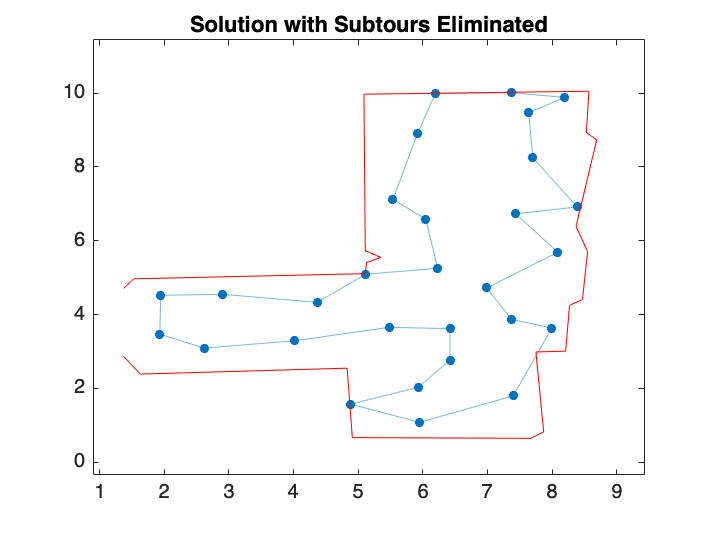

     0



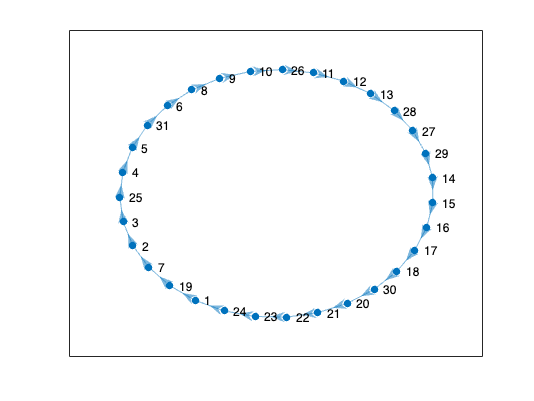


    % determine an optimal path passing through all polygons using TSP algorithm
    [~, polybox.nodeList] = directedTSP(polybox, room.Vertices);


    % identify the polygons that need to be merged
    box2merge = identifyBox2merge(mergeRob, polybox, editedMap);

#### `% MERGE BOUNDING BOXES`

    % configure waitbar to monitor merging process
    boxWait = waitbar(0,'Initializing Merging Process','Name','Merging Bounding Boxes...',...
        'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

    % configure a cancel button on waitbar
    setappdata(boxWait,'canceling',0);

    offset = 0; % counter to track the number of nodes removed from the original node list
    for j = 1:length(box2merge)
        % check if cancel button has been pressed
        if getappdata(boxWait,'canceling'); break; end

        % identify node to be merged by subtracting the offset from the current node value
        node = box2merge(j,1)-offset;

        % update waitbar and message
        waitbar(j/length(box2merge),boxWait,sprintf('Merging polygon %d of %d',j,length(box2merge)))

        % fprintf('%d\n',node+offset) % display current node being merged

        Gbox = polyConn(polybox.shape);    % get current polygon connectivity

        try
            % determine which neighbor to merge with
            neighbor2merge = polyNeighbor(Gbox, node, polybox.shape);

            % merge neighbor with current node
            polybox.shape(neighbor2merge) = union(polybox.shape(neighbor2merge),polybox.shape(node));

            offset = offset+1;  % increment offset value
            polybox.shape(node) = [];   % remove merged node from shape list
        catch
            fprintf('Node %d has no identified neighbors',node+offset)
            offset = offset+1;  % increment offset value
            polybox.shape(node) = [];   % remove neighborless node from shape list
        end
    end

    delete(boxWait) % delete waitbar

#### `% FINALIZE RESULTING POLYGONS`

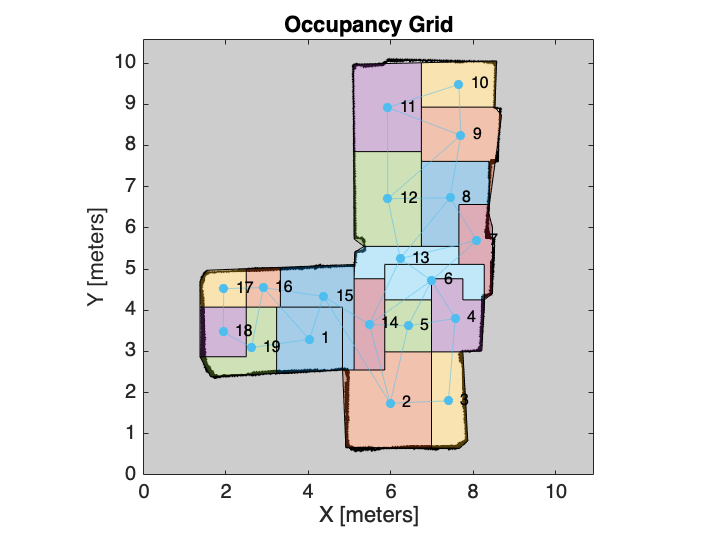

    % ensure that each polygon has one region and no unnecessary holes
    for i = 1:length(polybox.shape)
        % if multiple regions are identifed, create a bounding box to merge them together
        if polybox.shape(i).NumRegions > 1 || polybox.shape(i).NumHoles >= 1
            currentpoly = polybox.shape(i); % identify the current polygon

            % obtain bounding box XY limits
            [xlim,ylim] = boundingbox(currentpoly);

            % identify min and max of XY limits
            xmin = min(xlim); xmax = max(xlim);
            ymin = min(ylim); ymax = max(ylim);

            % generate a polyshape of the bounding box and replace the current
            % polygon with the bounding box
            polyMin = [xmin,ymin;xmax,ymin;xmax,ymax;xmin,ymax];
            currentpoly = polyshape(polyMin);

            % identify and remove any areas of the current polygon outside the room
            roomintsec = intersect(currentpoly,roomOutside);
            currentpoly = subtract(currentpoly,roomintsec);

            % remove any overlaps between other polyshapes
            for before = 1:i-1
                currentpoly = subtract(currentpoly,polybox.shape(before));
            end

            for after = i+1:length(polybox.shape)
                currentpoly = subtract(currentpoly,polybox.shape(after));
            end

            % remove any resulting slivers
            currentpoly = rmslivers(currentpoly,.05);

            % save the edited polygon to the original polygon index
            polybox.shape(i) = currentpoly;
        end
    end

    % update centroid values
    [x,y] = centroid(polybox.shape);
    polybox.centroid = [x;y]';

    % get current polygon connectivity
    Gbox = polyConn(polybox.shape);

    % visually inspect polygon connectivity
    figure; show(editedMap); hold on;
    plot(polybox.shape)
    plot(Gbox,'XData',polybox.centroid(:,1),'YData',polybox.centroid(:,2))
    hold off;

# of subtours: 4
# of subtours: 4
# of subtours: 3
# of subtours: 1


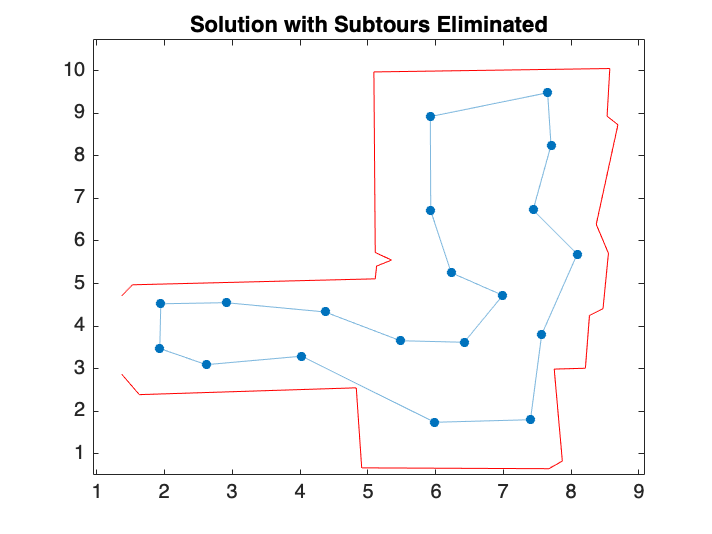

     0



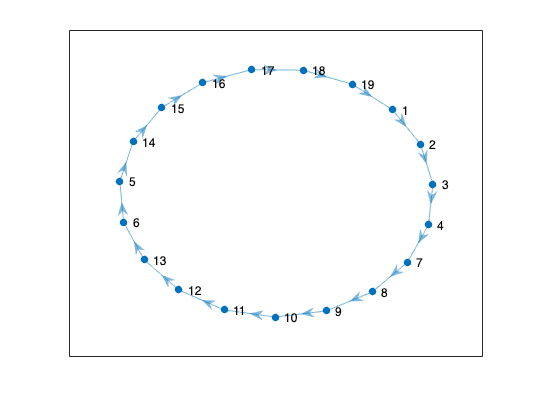


    % determine a final optimal path passing through all polygons using TSP algorithm
    [Gdir, polybox.nodeList] = directedTSP(polybox, room.Vertices);

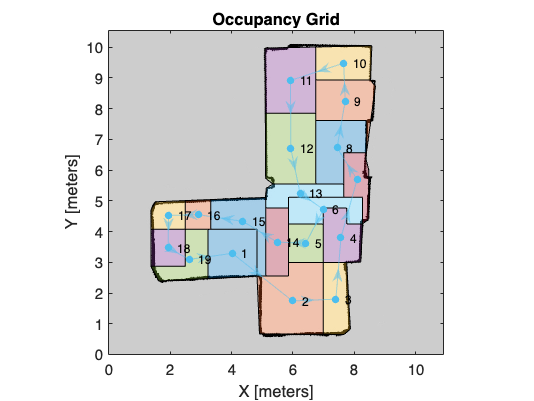


    % visually inspect the generated optimal path
    figure; show(editedMap); hold on;
    plot(polybox.shape)
    hGraph = plot(Gdir,'XData',polybox.centroid(:,1),'YData',polybox.centroid(:,2),'LineStyle','none');
    highlight(hGraph,Gdir,'LineStyle','-')
    hold off


    programTime = toc; % record strategy planning algorithm runtime

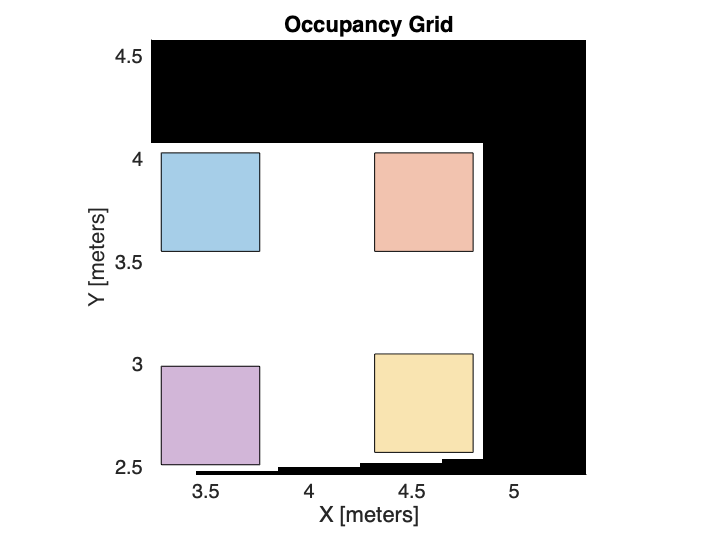

Coverage complete, stopped at...
    4.0600    3.4200



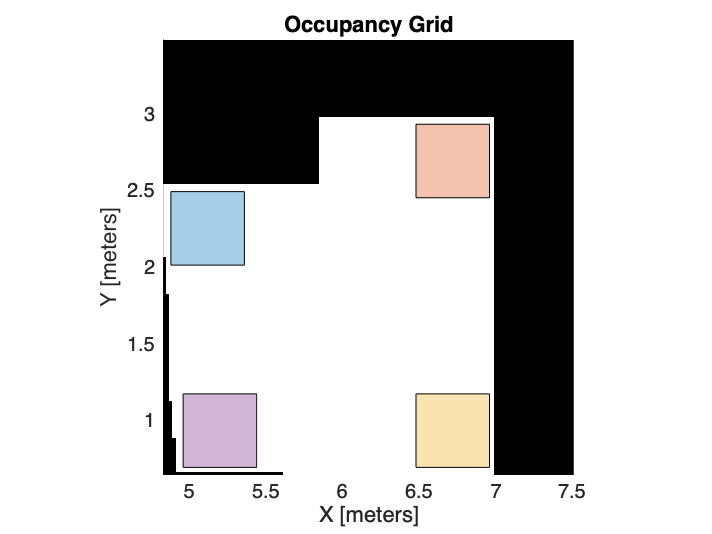

Coverage complete, stopped at...
    6.2200    1.9449



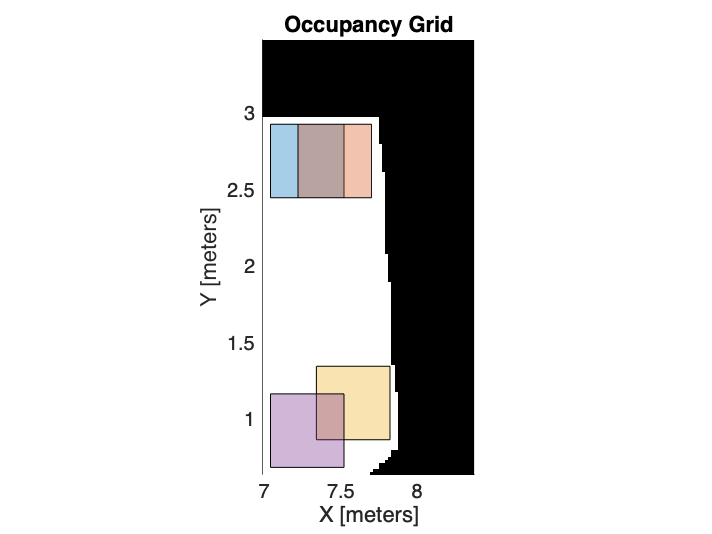

Coverage complete, stopped at...
    7.2802    1.5600



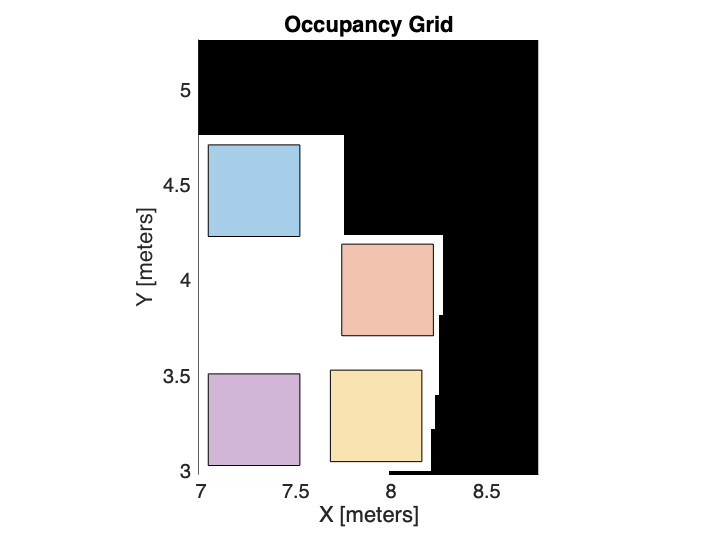

Coverage complete, stopped at...
    7.2802    3.7200



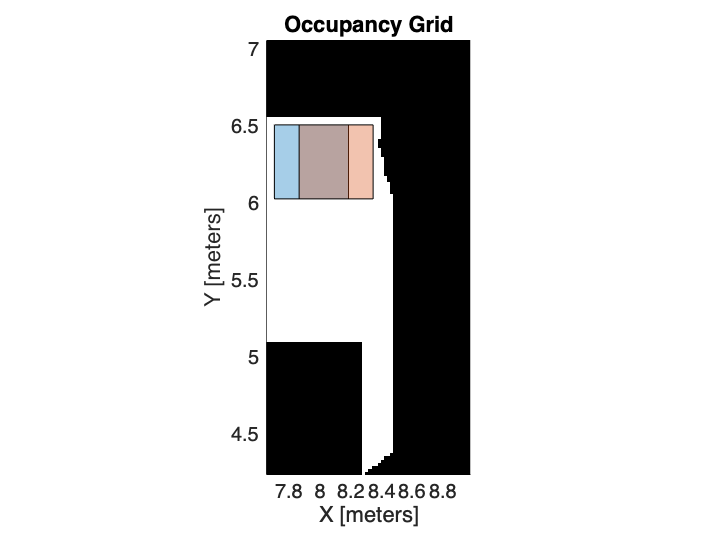

Coverage complete, stopped at...
    7.9452    6.2800



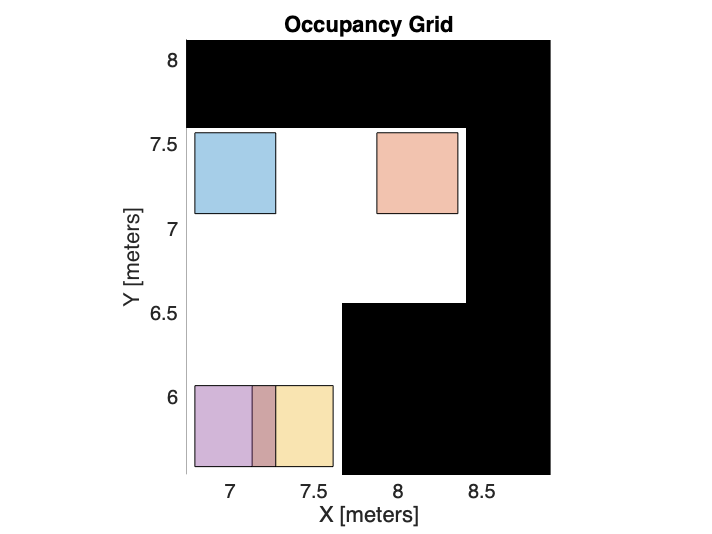

Coverage complete, stopped at...
    7.5341    6.9800



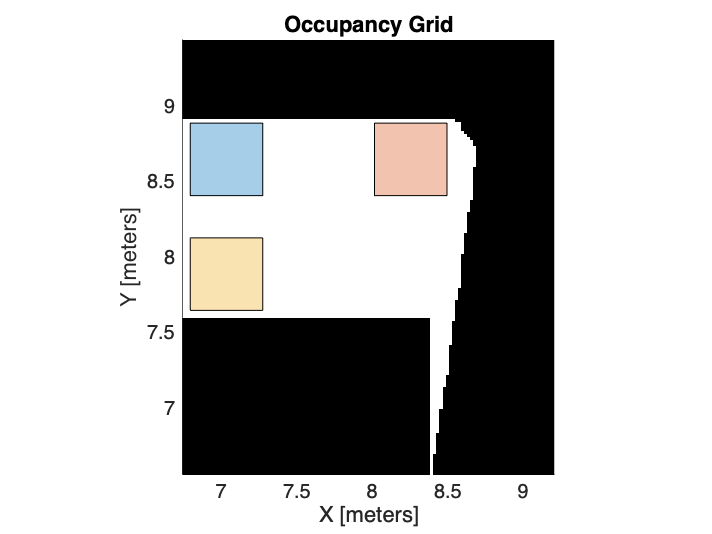

Coverage complete, stopped at...
    7.5341    8.2773



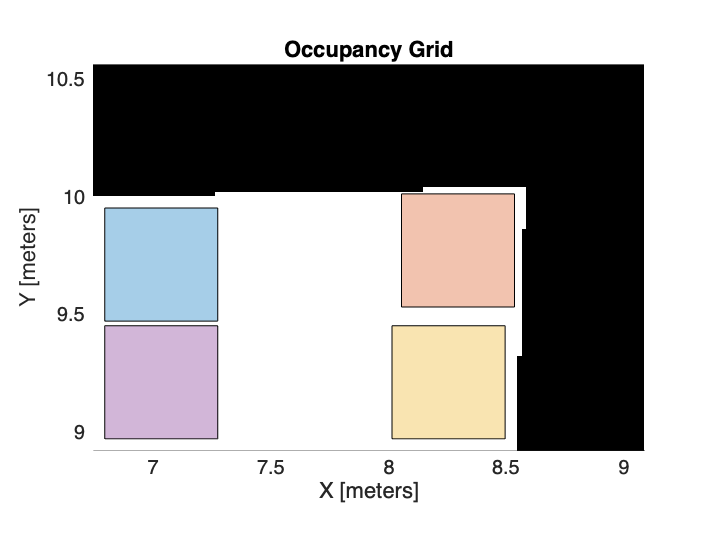

Coverage complete, stopped at...
    7.7941    9.4000



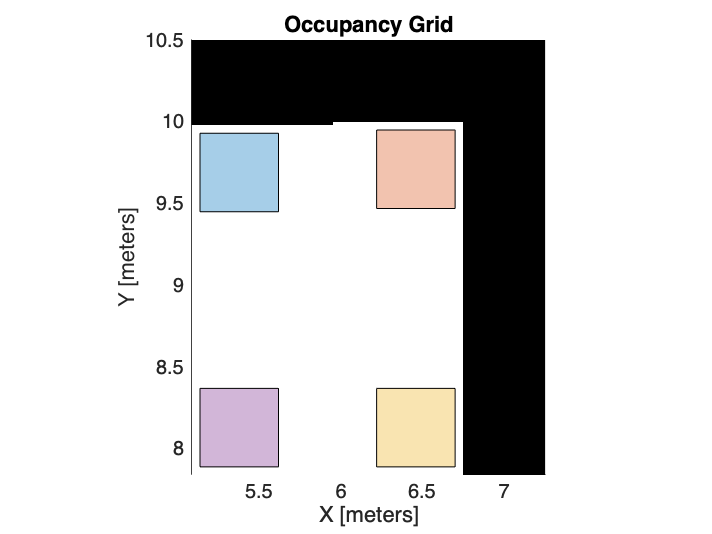

Coverage complete, stopped at...
    5.9600    8.5800



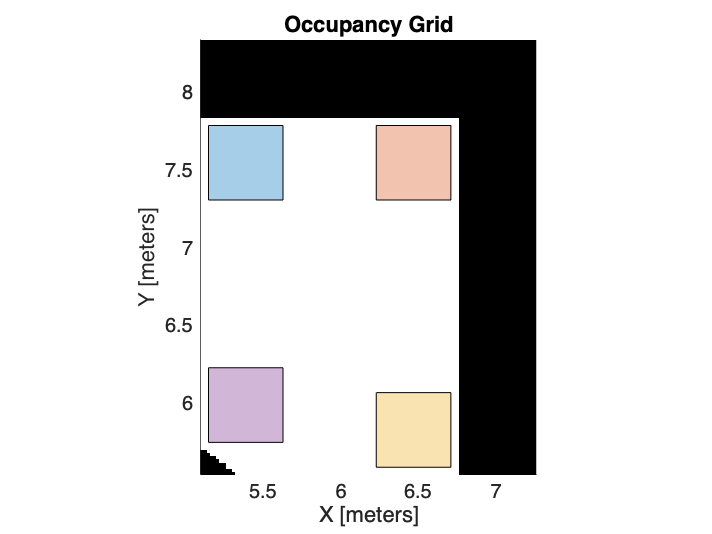

Coverage complete, stopped at...
    5.9700    6.9800



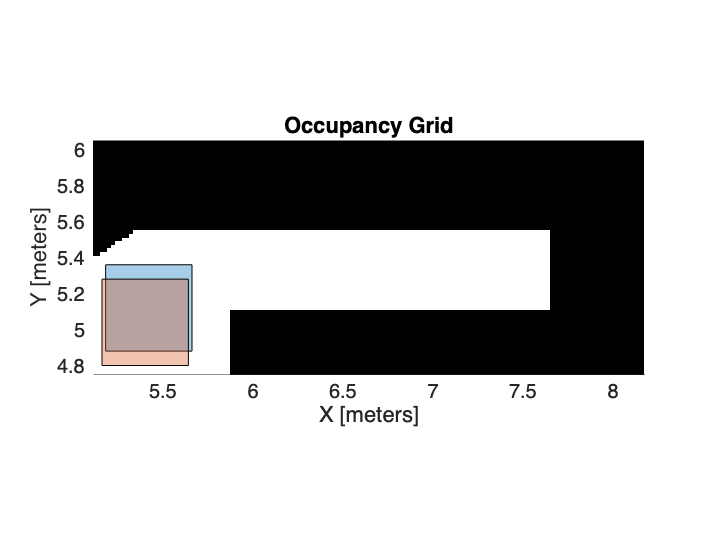

Coverage complete, stopped at...
    5.4000    5.4332



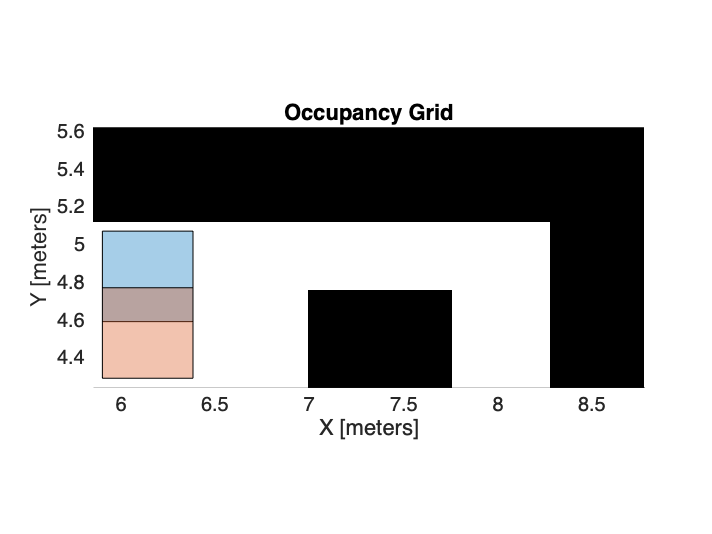

Coverage complete, stopped at...
    6.6434    4.5400



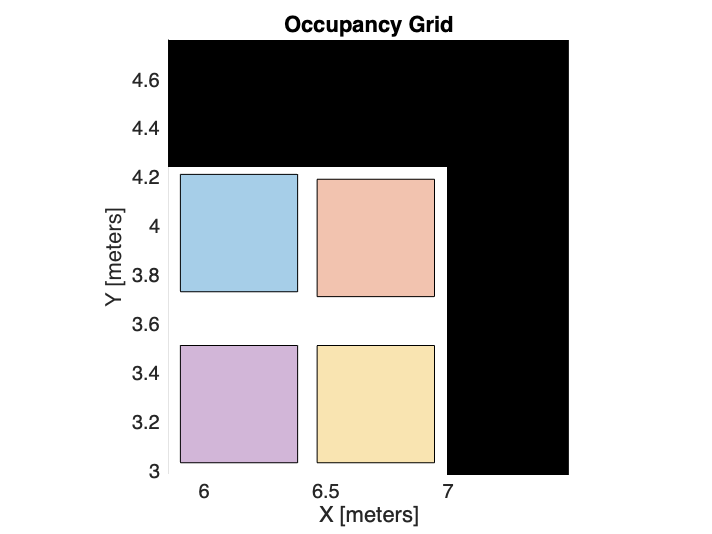

Coverage complete, stopped at...
    6.1434    3.6000



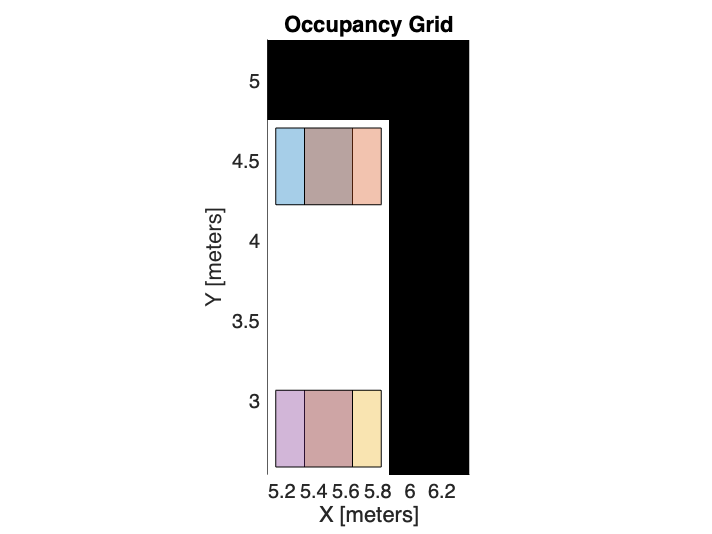

Coverage complete, stopped at...
    5.5800    3.3400



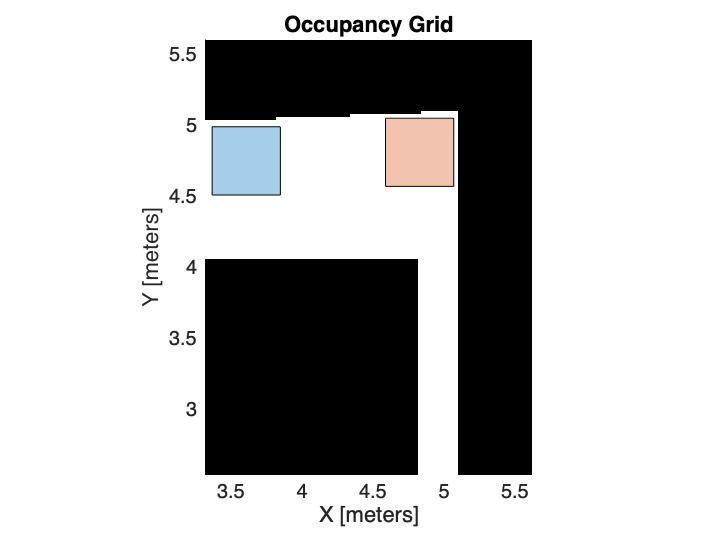

Coverage complete, stopped at...
    4.1100    4.7600



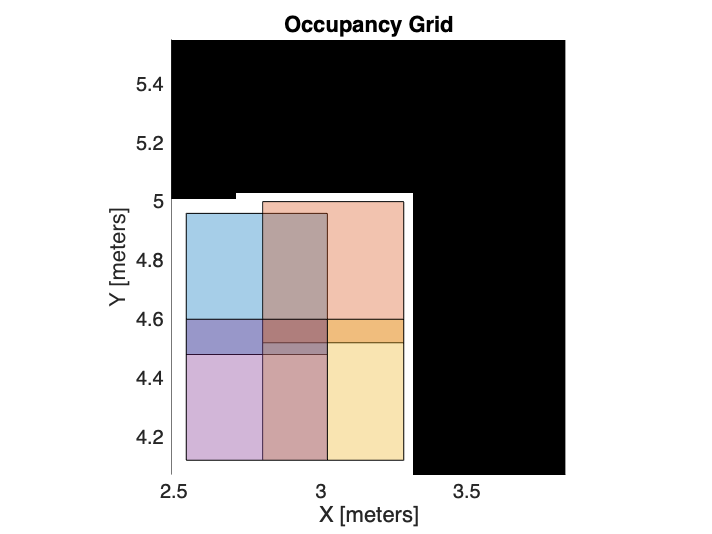

Coverage complete, stopped at...
    3.0433    4.3859



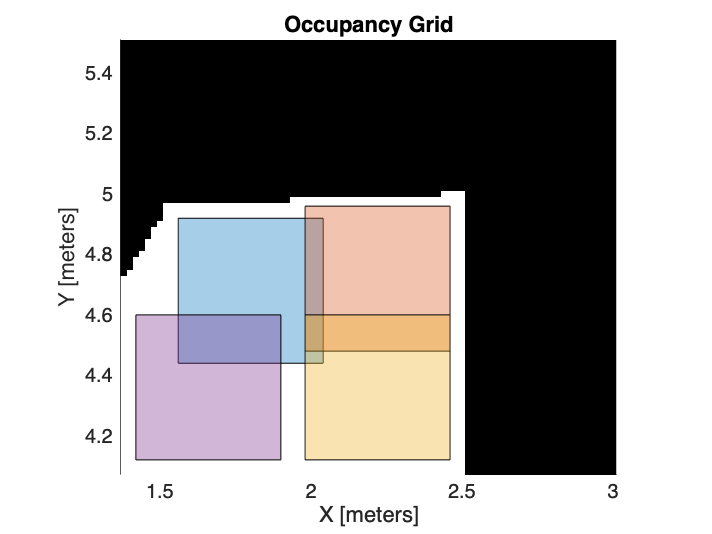

Coverage complete, stopped at...
    2.2200    4.3459



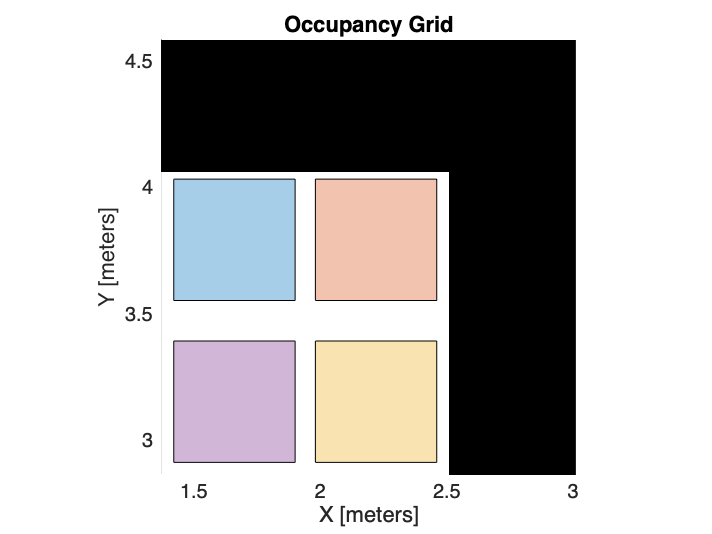

Coverage complete, stopped at...
    2.2200    3.4200



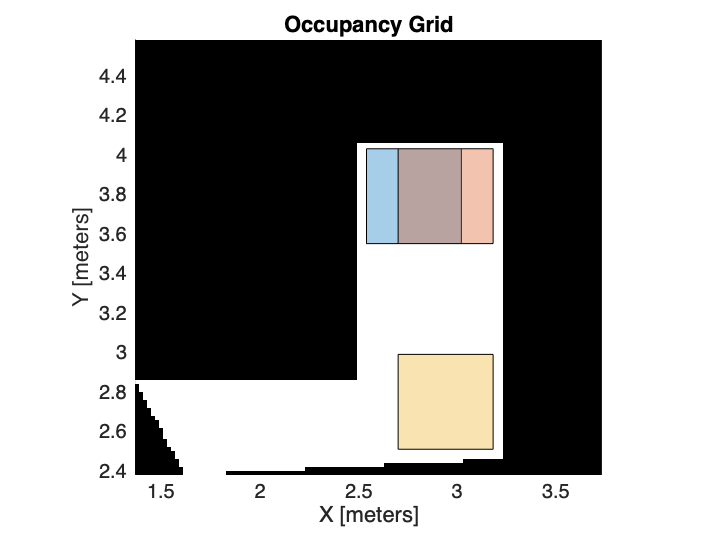

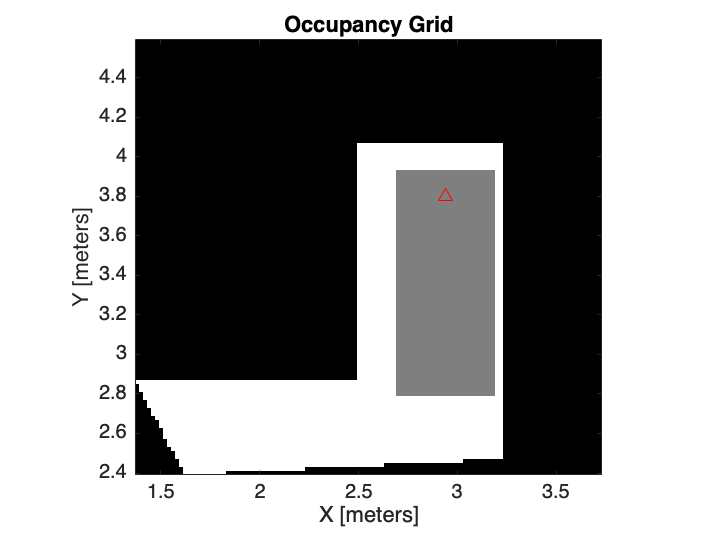

Coverage complete, stopped at...
    2.9400    3.8000



Total simulation runtime: 59.24

Total turn count: 108

Total path length: 59.77

Total overlap: 37

Minimum task overlap: 0

Maximum task overlap: 3

Average overlap per task: 1.95

Coverage efficiency: 65.56%

Number of deadlock events: 0

Strategy planning algorithm runtime: 33.75

Number of triangles within mesh: 33

Number of tasks: 19

    % if the number of robots is 1 assign all tasks to one robot
    if numRobots == 1
        deadlock_cntr = 0;  % initialize a variable to count the number of encountered deadlocks
        % loop through each task for complete coverage
        for i = 1:length(polybox.shape)

            % get local occupancy map and starting location of current task
            [localMap, startXY] = poly2occgrid(polybox, i, rawMap, rob, cornerLoc, resolution);

            % convert starting location to IJ coordinates
            startIJ = world2grid(localMap,startXY);

            % call path planning algorithm to perform complete coverage
            figure;
            [localMap,time(i,1),turnCount(i,1),overlap(i,1),pathLength(i,1),deadlock_cntr] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr);

            % determine the number of cleaned and uncleaned cells of current task
            localOcc = occupancyMatrix(localMap);
            clean(i,1) = length(find((localOcc>.4)&(localOcc<.6)));
            unclean(i,1) = length(find(localOcc<.1));
        end

        % display simualtion data
        fprintf("Total simulation runtime: %.2f",sum(time))
        fprintf("Total turn count: %d",sum(turnCount))
        fprintf("Total path length: %.2f",sum(pathLength))

        fprintf("Total overlap: %d",sum(overlap))
        fprintf("Minimum task overlap: %d",min(overlap))
        fprintf("Maximum task overlap: %d",max(overlap))
        fprintf("Average overlap per task: %.2f",mean(overlap))

        covEff = sum(clean) / (sum(unclean)+sum(clean));
        fprintf("Coverage efficiency: %.2f%%",covEff*100)

        fprintf("Number of deadlock events: %d",deadlock_cntr)
        fprintf("Strategy planning algorithm runtime: %.2f",programTime)
        fprintf("Number of triangles within mesh: %d",length(tri.list))
        fprintf("Number of tasks: %d",length(polybox.shape))

# `Task Allocation`

    elseif numRobots == 2
        task_list = polybox.nodeList(:,1); % assign the node list first column to the task list
        task_list(end,:) = [];  % remove the repeated node at bottom of list

        % divide the task list into segments according to the number of robots
        task_segments = allocateTasks(task_list, numRobots)

        delete(gcp('nocreate'));    % end any background parallel pool processes
        parpool(2); % start a parallel pool process

        % tag naming reference
        % tag 1 -> robot1retask
        % tag 2 -> robot2retask
        % tag 3 -> robot1done
        % tag 4 -> robot2done
        % tag 5 -> robot1onetaskleft
        % tag 6 -> robot2onetaskleft

        % set flag variables
        finished = 0;
        otherFinished = 0;
        reAllocateTasks = 0;
        robot1onetaskleft = 0;
        robot2onetaskleft = 0;
        %         clear retasked_segments deadlock_cntr

        % initialize simulation data variables
        tot_time = 0;
        tot_turnCount = 0;
        tot_overlap = 0;
        tot_pathLength = 0;
        clean = 0;
        unclean = 0;

        if enableRetasking
            spmd
                if spmdIndex == 1
                    try
                        disp('Robot 1: Cleaning in progress')

                        deadlock_cntr{spmdIndex} = 0;   % initialize variable on worker to count the number of encountered deadlocks
                        % loop through the assigned tasks for complete coverage
                        for currentTask = 1:height(task_segments{spmdIndex})

                            % check if any message received from other robot
                            if spmdProbe
                                otherFinished = spmdReceive('any',4)   % receive robot2done with tag 4

                                % check if the received message indicates the other robot has finished
                                if otherFinished == 1
                                    disp('Robot 1: Robot 2 has finished')

                                    % check if the number of remaining tasks is greater than 1
                                    if (height(task_segments{spmdIndex}) - currentTask) > 1
                                        reAllocateTasks = 1;    % set reAllocateTasks flag to 1
                                        robot1onetaskleft = 0;  % set robot1onetaskleft flag to 0
                                        spmdSend(robot1onetaskleft,2,5) % send robot1onetaskleft to robot 2 with tag 5
                                        spmdBarrier      % barrier #1; update robot 2 there is more than 1 task remaining for robot 1
                                        break;  % break out of current loop
                                    else
                                        disp("Robot 1: 1 task remaining")
                                        robot1onetaskleft = 1;  % set robot1onetaskleft to 1
                                        spmdSend(robot1onetaskleft,2,5) % send robot1onetaskleft to robot 2 with tag 5
                                        spmdBarrier     % barrier #1; update robot 2 there is 1 task remaining for robot 1
                                    end
                                end
                            end

                            % get local occupancy map and starting location of current task
                            [localMap, startXY] = poly2occgrid(polybox, task_segments{spmdIndex}(currentTask), rawMap, rob, cornerLoc, resolution);

                            % convert starting location to IJ coordinates
                            startIJ = world2grid(localMap,startXY);

                            % call path planning algorithm to perform complete coverage
                            figure;
                            [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                            % determine the number of cleaned and uncleaned cells of current task
                            localOcc = occupancyMatrix(localMap);
                            clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                            unclean = unclean+length(find(localOcc<.1));

                            % update simulation data
                            tot_time = tot_time +time;
                            tot_turnCount = tot_turnCount+turnCount;
                            tot_overlap = tot_overlap+overlap;
                            tot_pathLength = tot_pathLength+pathLength;

                            % report cleaning progress
                            fprintf('Robot %d: Task %d complete. Progress: %d of %d\n', ...
                                spmdIndex,task_segments{spmdIndex}(currentTask),currentTask,length(task_segments{spmdIndex}))
                        end

                        % enter this code block if the reAllocateTasks flag is set to 1
                        if reAllocateTasks
                            % report task reallocation is occurring and task stopped on
                            fprintf('Robot %d: Reallocating tasks. Stopped on Task %d\n', ...
                                spmdIndex,task_segments{spmdIndex}(currentTask))

                            % remove already completed tasks from current task list
                            for i = 1:currentTask-1
                                task_segments{spmdIndex}(1,:) = [];
                            end

                            % reallocate remaining tasks
                            retasked_segments = allocateTasks(task_segments{spmdIndex},num_robots)

                            spmdSend(retasked_segments,2,1)   % send robot1retask to robot 2 with tag 1

                            spmdBarrier     % barrier #2; send robot 1 retask to robot 2 and wait

                            % loop through the reassigned tasks for complete coverage
                            for currentTask = 1:length(retasked_segments{1})

                                % get local occupancy map and starting location of current task
                                [localMap, startXY] = poly2occgrid(polybox, retasked_segments{1}(currentTask), rawMap, rob, cornerLoc, resolution);

                                % convert starting location to IJ coordinates
                                startIJ = world2grid(localMap,startXY);

                                % call path planning algorithm to perform complete coverage
                                figure;
                                [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                                % determine the number of cleaned and uncleaned cells of current task
                                localOcc = occupancyMatrix(localMap);
                                clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                                unclean = unclean+length(find(localOcc<.1));

                                % update simulation data
                                tot_time = tot_time +time;
                                tot_turnCount = tot_turnCount+turnCount;
                                tot_overlap = tot_overlap+overlap;
                                tot_pathLength = tot_pathLength+pathLength;

                                % report cleaning progress
                                fprintf('Robot %d: Reallocated Task %d complete\nProgress: %d of %d\n', ...
                                    spmdIndex,retasked_segments{1}(currentTask),currentTask,length(retasked_segments{1}))
                            end
                        end

                        finished = 1;   % set finished flag to 1
                        disp('Robot 1: Done')   % report robot 1 has completed its assigned tasks

                        % enter this code block if the finished flag is set to 1 and the otherFinished flag is set to 0
                        if (finished == 1) && (otherFinished == 0)
                            spmdSend(finished,2,3)    % send robot1done to robot 2 with tag 3

                            spmdBarrier     % barrier #3; communicate robot 1 has finished before robot 2; wait for task remaining update from robot 1

                            robot2onetaskleft = spmdReceive("any",6)    % receive2onetaskleft with tag 6

                            % check status of one task remaining flag
                            if robot2onetaskleft == 0
                                disp("Robot 1: Receiving reallocated tasks from Robot 2")

                                spmdBarrier     % barrier #4; wait for robot 2 retask update

                                retasked_segments = spmdReceive("any",2)    % receive robot2retask with tag 2

                                % loop through the received reassigned tasks for complete coverage
                                for currentTask = 1:length(retasked_segments{2})

                                    % get local occupancy map and starting location of current task
                                    [localMap, startXY] = poly2occgrid(polybox, retasked_segments{2}(currentTask), rawMap, rob, cornerLoc, resolution);

                                    % convert starting location to IJ coordinates
                                    startIJ = world2grid(localMap,startXY);

                                    % call path planning algorithm to perform complete coverage
                                    figure;
                                    [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                                    % determine the number of cleaned and uncleaned cells of current task
                                    localOcc = occupancyMatrix(localMap);
                                    clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                                    unclean = unclean+length(find(localOcc<.1));

                                    % update simulation data
                                    tot_time = tot_time+time;
                                    tot_turnCount = tot_turnCount+turnCount;
                                    tot_overlap = tot_overlap+overlap;
                                    tot_pathLength = tot_pathLength+pathLength;

                                    % report cleaning progress
                                    fprintf('Robot %d: Reallocated Task %d complete\nProgress: %d of %d\n', ...
                                        spmdIndex,retasked_segments{2}(currentTask),currentTask,length(retasked_segments{2}))
                                end
                            else
                                disp("Robot 1: Bypassing retask since 1 task remaining on Robot 2")
                            end
                        end
                        spmdBarrier % barrier #0; wait for both robots to complete assigned tasks
                    catch
                        disp("Both robots have finished at the same time")
                    end
                end

                if spmdIndex == 2
                    try
                        disp('Robot 2: Cleaning in progress')

                        deadlock_cntr{spmdIndex} = 0;   % initialize variable on worker to count the number of encountered deadlocks
                        % loop through the assigned tasks for complete coverage
                        for currentTask = 1:height(task_segments{spmdIndex})

                            % check if any message received from other robot
                            if spmdProbe
                                otherFinished = spmdReceive("any",3)   % receive robot1done with tag 3

                                % check if the received message indicates the other robot has finished
                                if otherFinished == 1
                                    disp('Robot 2: Robot 1 has finished')

                                    % check if the number of remaining tasks is greater than 1
                                    if (height(task_segments{spmdIndex}) - currentTask) > 1
                                        reAllocateTasks = 1;    % set reAllocateTasks flag to 1
                                        robot2onetaskleft = 0;  % set robot2onetaskleft flag to 0
                                        spmdSend(robot2onetaskleft,1,6) % send robot2onetaskleft to robot 1 with tag 6
                                        spmdBarrier     % barrier #3; update robot 1 there is more than 1 task remaining for robot 2
                                        break;
                                    else
                                        disp("Robot 2: 1 task remaining")
                                        robot2onetaskleft = 1;  % set robot1onetaskleft to 1
                                        spmdSend(robot2onetaskleft,1,6) % send robot2onetaskleft to robot 1 with tag 6
                                        spmdBarrier     % barrier #3; update robot 1 there is 1 task remianing for robot 2
                                    end
                                end
                            end

                            % get local occupancy map and starting location of current task
                            [localMap, startXY] = poly2occgrid(polybox, task_segments{spmdIndex}(currentTask), rawMap, rob, cornerLoc, resolution);

                            % convert starting location to IJ coordinates
                            startIJ = world2grid(localMap,startXY);

                            % call path planning algorithm to perform complete coverage
                            figure;
                            [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                            % determine the number of cleaned and uncleaned cells of current task
                            localOcc = occupancyMatrix(localMap);
                            clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                            unclean = unclean+length(find(localOcc<.1));

                            % update simulation data
                            tot_time = tot_time +time;
                            tot_turnCount = tot_turnCount+turnCount;
                            tot_overlap = tot_overlap+overlap;
                            tot_pathLength = tot_pathLength+pathLength;

                            % report cleaning progress
                            fprintf('Robot %d: Task %d complete\nProgress %d of %d\n', ...
                                spmdIndex,task_segments{spmdIndex}(currentTask),currentTask,length(task_segments{spmdIndex}))
                        end

                        % enter this code block if the reAllocateTasks flag is set to 1
                        if reAllocateTasks
                            % report task reallocation is occurring and task stopped on
                            fprintf('Robot %d: Reallocating tasks. Stopped on Task %d\n', ...
                                spmdIndex,task_segments{spmdIndex}(currentTask))

                            % remove already completed tasks from current task list
                            for i = 1:currentTask-1
                                task_segments{spmdIndex}(1,:) = [];   % remove already completed tasks
                            end

                            % reallocate remaining tasks
                            retasked_segments = allocateTasks(task_segments{spmdIndex},num_robots)

                            spmdSend(retasked_segments,1,2)   % send robot2retask to robot 1 with tag 2

                            spmdBarrier     % barrier #4; send robot 2 retask to robot 1 and wait

                            % loop through the reassigned tasks for complete coverage
                            for currentTask = 1:length(retasked_segments{1})

                                % get local occupancy map and starting location of current task
                                [localMap, startXY] = poly2occgrid(polybox, retasked_segments{1}(currentTask), rawMap, rob, cornerLoc, resolution);

                                % convert starting location to IJ coordinates
                                startIJ = world2grid(localMap,startXY);

                                % call path planning algorithm to perform complete coverage
                                figure;
                                [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                                % determine the number of cleaned and uncleaned cells of current task
                                localOcc = occupancyMatrix(localMap);
                                clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                                unclean = unclean+length(find(localOcc<.1));

                                % update simulation data
                                tot_time = tot_time +time;
                                tot_turnCount = tot_turnCount+turnCount;
                                tot_overlap = tot_overlap+overlap;
                                tot_pathLength = tot_pathLength+pathLength;

                                % report cleaning progress
                                fprintf('Robot %d: Reallocated Task %d complete\nProgress %d of %d\n', ...
                                    spmdIndex,retasked_segments{1}(currentTask),currentTask,length(retasked_segments{1}))
                            end
                        end

                        finished = 1;   % set finished flag to 1
                        disp('Robot 2 done')    % report robot 2 has completed its assigned tasks

                        % enter this code block if the finished flag is set to 1 and the otherFinished flag is set to 0
                        if (finished == 1) && (otherFinished == 0)
                            spmdSend(finished,1,4)    % send robot2done to robot 1 with tag 4

                            spmdBarrier     % barrier #1; communicate robot 2 has finished before robot 1; wait for task remaining update from robot 1

                            robot1onetaskleft = spmdReceive("any",5)    % receive robot1onetaskleft with tag 5

                            % check status of one task remaining flag
                            if robot1onetaskleft == 0
                                disp("Robot 2: Receiving reallocated tasks from Robot 1")

                                spmdBarrier     % barrier #2; wait for robot 1 retask update

                                retasked_segments = spmdReceive("any",1)    % receive robot1retask with tag 1

                                % loop through the received reassigned tasks for complete coverage
                                for currentTask = 1:length(retasked_segments{2})

                                    % get local occupancy map and starting location of current task
                                    [localMap, startXY] = poly2occgrid(polybox, retasked_segments{2}(currentTask), rawMap, rob, cornerLoc, resolution);

                                    % convert starting location to IJ coordinates
                                    startIJ = world2grid(localMap,startXY);

                                    % call path planning algorithm to perform complete coverage
                                    figure;
                                    [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                                    % determine the number of cleaned and uncleaned cells of current task
                                    localOcc = occupancyMatrix(localMap);
                                    clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                                    unclean = unclean+length(find(localOcc<.1));

                                    % update simulation data
                                    tot_time = tot_time+time;
                                    tot_turnCount = tot_turnCount+turnCount;
                                    tot_overlap = tot_overlap+overlap;
                                    tot_pathLength = tot_pathLength+pathLength;

                                    % report cleaning progress
                                    fprintf('Robot %d: Reallocated Task %d complete\nProgress %d of %d\n', ...
                                        spmdIndex,retasked_segments{2}(currentTask),currentTask,length(retasked_segments{2}))
                                end
                            else
                                disp("Robot 2: Bypassing retask since 1 task remaining on Robot 1")
                            end
                        end
                        spmdBarrier % barrier #0; wait for both robots to complete assigned tasks
                    catch
                        disp("Both robots have finished at the same time")
                    end
                end
            end
        else
            spmd
                if spmdIndex == 1
                    disp('Robot 1: Cleaning in progress')

                    deadlock_cntr{spmdIndex} = 0;   % initialize variable on worker to count the number of encountered deadlocks
                    % loop through the assigned tasks for complete coverage
                    for currentTask = 1:height(task_segments{spmdIndex})

                        % get local occupancy map and starting location of current task
                        [localMap, startXY] = poly2occgrid(polybox, task_segments{spmdIndex}(currentTask), rawMap, rob, cornerLoc, resolution);

                        % convert starting location to IJ coordinates
                        startIJ = world2grid(localMap,startXY);

                        % call path planning algorithm to perform complete coverage
                        figure;
                        [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                        % determine the number of cleaned and uncleaned cells of current task
                        localOcc = occupancyMatrix(localMap);
                        clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                        unclean = unclean+length(find(localOcc<.1));

                        % update simulation data
                        tot_time = tot_time +time;
                        tot_turnCount = tot_turnCount+turnCount;
                        tot_overlap = tot_overlap+overlap;
                        tot_pathLength = tot_pathLength+pathLength;

                        % report cleaning progress
                        fprintf('Robot %d: Task %d complete. Progress: %d of %d\n', ...
                            spmdIndex,task_segments{spmdIndex}(currentTask),currentTask,length(task_segments{spmdIndex}))
                    end

                    disp('Robot 1: Done')   % report robot 1 has completed its assigned tasks
                    spmdBarrier % barrier #0; wait for both robots to complete assigned tasks
                end

                if spmdIndex == 2
                    disp('Robot 2: Cleaning in progress')

                    deadlock_cntr{spmdIndex} = 0;   % initialize variable on worker to count the number of encountered deadlocks
                    % loop through the assigned tasks for complete coverage
                    for currentTask = 1:height(task_segments{spmdIndex})

                        % get local occupancy map and starting location of current task
                        [localMap, startXY] = poly2occgrid(polybox, task_segments{spmdIndex}(currentTask), rawMap, rob, cornerLoc, resolution);

                        % convert starting location to IJ coordinates
                        startIJ = world2grid(localMap,startXY);

                        % call path planning algorithm to perform complete coverage
                        figure;
                        [localMap,time,turnCount,overlap,pathLength,deadlock_cntr{spmdIndex}] = cleanRoomSimTest(localMap,startIJ,deadlock_cntr{spmdIndex});

                        % determine the number of cleaned and uncleaned cells of current task
                        localOcc = occupancyMatrix(localMap);
                        clean = clean+length(find((localOcc>.4)&(localOcc<.6)));
                        unclean = unclean+length(find(localOcc<.1));

                        % update simulation data
                        tot_time = tot_time +time;
                        tot_turnCount = tot_turnCount+turnCount;
                        tot_overlap = tot_overlap+overlap;
                        tot_pathLength = tot_pathLength+pathLength;

                        % report cleaning progress
                        fprintf('Robot %d: Task %d complete\nProgress %d of %d\n', ...
                            spmdIndex,task_segments{spmdIndex}(currentTask),currentTask,length(task_segments{spmdIndex}))
                    end

                    disp('Robot 2 done')    % report robot 2 has completed its assigned tasks
                    spmdBarrier % barrier #0; wait for both robots to complete assigned tasks
                end
            end
        end

        % display simualtion data
        runtime = [tot_time{:}];
        fprintf("Robot 1 simulation runtime: %.2fs",runtime(1))
        fprintf("Robot 2 simulation runtime: %.2fs",runtime(2))
        fprintf("Idle time: %.2fs",max(runtime)-min(runtime))

        retask = [reAllocateTasks{:}];
        if any(retask); fprintf("Tasks reallocated"); else; fprintf("Tasks not reallocated"); end

        fprintf("Robot 1 turn count: %d",tot_turnCount{1})
        fprintf("Robot 2 turn count: %d",tot_turnCount{2})

        fprintf("Robot 1 path length: %.2f",tot_pathLength{1})
        fprintf("Robot 2 path length: %.2f",tot_pathLength{2})

        fprintf("Robot 1 overlap: %d",tot_overlap{1})
        fprintf("Robot 2 overlap: %d",tot_overlap{2})

        covEff1 = clean{1} / (clean{1}+unclean{1});
        fprintf("Robot 1 coverage efficiency: %.2f%%",covEff1*100)
        covEff2 = clean{2} / (clean{2}+unclean{2});
        fprintf("Robot 2 coverage efficiency: %.2f%%",covEff2*100)
        covEff = (clean{1}+clean{2}) / (clean{1}+clean{2}+unclean{1}+unclean{2});
        fprintf("Total coverage efficiency: %.2f%%",covEff*100)

        deadlock = [deadlock_cntr{:}]; deadlock = cell2mat(deadlock);
        fprintf("Robot 1 deadlock events: %d",deadlock(1))
        fprintf("Robot 2 deadlock events: %d",deadlock(2))

        fprintf("Strategy planning algorithm runtime: %.2fs",programTime)
        fprintf("Number of triangles within mesh: %d",length(tri.list))
        fprintf("Number of tasks: %d",length(task_list))

    else
        disp("Current program can only account for 1 or 2 robots")
    end
end